clear;

M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];

% Синтез модального регулятора 
Gamma_r = [-1 1 0 0; 0 -1 1 0; 0 0 -1 1; 0 0 0 -1];
%Gamma_r = [-3 0 0 0; 0 -2.5 0 0; 0 0 -2 0; 0 0 0 -1.5];
%Gamma_r = [-0.5 0 0 0; 0 -0.4 0 0; 0 0 -0.3 0; 0 0 0 -0.2];

Y_r = [1 1 1 1];

cvx_begin sdp

variable P_r(4, 4)
A*P_r-P_r*Gamma_r == B*Y_r;

cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


A*P_r;
P_r;
det(P_r);
K = -Y_r*pinv(P_r)

K = 1.0e+03 *

    0.0469    0.1875   -5.5258   -2.1628



eig(A+B*K)

ans =   -1.0001 + 0.0001i
  -1.0001 - 0.0001i
  -0.9999 + 0.0001i
  -0.9999 - 0.0001i




x_07 = [0.01; 0.01; 0.01; 0.01];
x_00 = [0; 0; 0; 0];
x_0 = x_07;
x_0_h = x_00;
f = 0;

% Временной интервал
tspan = [0 100];

%наблюдатель пониженной размерности

%Gamma_o2 = [-1 0; 0 -1.5];
Gamma_o2 = [-5 0; 0 -6];
Yo2 = [1 1;1 1]

Yo2 =      1     1
     1     1


%Uo2 = [Yo2 Gamma_o2*Yo2];
%det(Uo2)

cvx_begin sdp

variable Q_o2(2, 4);

Gamma_o2*Q_o2-Q_o2*A==Yo2*C;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Q_o2

Q_o2 =    -0.2000    0.0400   -0.2636    0.0527
   -0.1667    0.0278   -0.2003    0.0334



z_01 = [0; 0];
z_0 = z_01;

in_xz = [x_0; z_0];
D_ = [D(1); D(2)];
QB_YD = Q_o2*B;

[t, states] = ode45(@(t,z) observer_wrapper(t,z,K,Q_o2,Gamma_o2,Yo2,QB_YD,C,D_,f,m,M,l,g), tspan, in_xz);

x_real = states(:,1:4);
z_hat = states(:,5:6);

% Построение ошибки оценки
x_hat_full = zeros(length(t),4);
for i = 1:length(t)
    x_hat_full(i,:) = estimate_x(C*x_real(i,:)', z_hat(i,:)', Q_o2, C, D_, 0)';
end

u_restore = zeros(length(t), 1);

for i = 1:length(t)
    u_restore(i, :) = K*x_hat_full(i,:)';
end

 


max_phi = max(x_real(:,3))

max_phi = 0.0172

min(x_real(:,3))

ans = -0.0099

max_a = max(x_real(:,1))

max_a = 0.0169

min(x_real(:,1))

ans = -0.1578

max_u = max( u_restore(:, 1))

max_u = 304.0508

min(u_restore(:, 1))

ans = -156.8159


idx = find(abs(x_real(:,3)) >= 0.0001);
t_cross1 = t(idx(end));

idx2 = find(abs(x_real(:,1)) >= 0.0001);
t_cross2 = t(idx2(end));
idx3 = find(abs(u_restore(:,1)) >= 0.0001);
t_cross3 = t(idx3(end))

t_cross3 = 100


tt = max(t_cross1, t_cross2)

tt = 13.0652

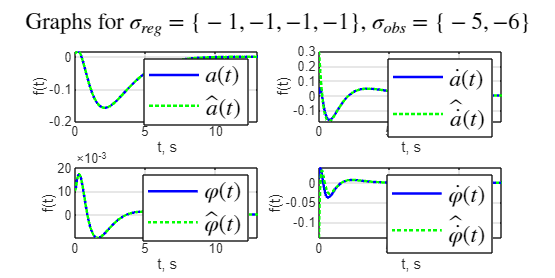






% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x_real(:,1), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat_full(:,1), 'g:', 'LineWidth',1.5); 
legend('$a(t)$', '$\hat{a}(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 13])
grid()
hold off

subplot(2,2,2);
plot(t, x_real(:,2), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat_full(:,2), 'g:', 'LineWidth',1.5); 
legend('$\dot{a}(t)$','$\hat{\dot{a}}(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 13])
grid()
hold off

subplot(2,2,3);
plot(t, x_real(:,3), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat_full(:,3), 'g:', 'LineWidth',1.5); 
legend('$\varphi(t)$','$\hat{\varphi}(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 13])
grid()
hold off

subplot(2,2,4);
plot(t, x_real(:,4), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat_full(:,4), 'g:', 'LineWidth',1.5); 
legend('$\dot{\varphi}(t)$','$\hat{\dot{\varphi}}(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 13])
grid()
hold off


sgtitle('Graphs for $\sigma_{reg} = \{-1, -1, -1, -1\}$, $\sigma_{obs} = \{-5, -6 \}$','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\' ...
    'pic_fix\3_x_k1l2.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

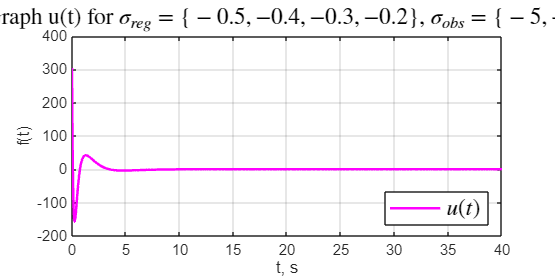




figure('Position', [100 100 800 400])
plot(t, u_restore, 'm-', 'LineWidth',1.5);
legend('$u(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
title('Graph u(t) for $\sigma_{reg} = \{-0.5, -0.4, -0.3, -0.2\}$, $\sigma_{obs} = \{-5, -6 \}$','Interpreter','latex',  'FontSize', 14)
xlim([0 40])
grid()



full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\' ...
    'pic_fix\3_u_k3l2.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);

